# Model Predictive Operational Point Transition

## Goals

- **Formulate Operational Point Transitions as Optimization Problems:** We formulate an optimization problem to determine the optimal change in control settings during an operational point transition.

- **Surrogate Model-Based Optimization:** The surrogate optimization framework introduced here solves three operational point transition examples.

- **Physics-Based Approach Comparison:** We show the formulated optimization to be intractable if physics-based models are utilize

## High-Level Highlights

Transitioning between operating points in a complex system can be challenging if constraints need to be adhered to. We first cast operational transitions with constraints as an optimization problem and then use the previously introduced surrogate model-based optimization framework to solve the formulated problem. The surrogate model-based optimization framework solves the problem quickly and robustly. Furthermore, we show that using a physics-based simulator for optimization will render this problem infeasible.

## Operational Point Transitions 

Suppose an operator would like to transition between two steady-state system operational points. If they were to change the control settings abruptly, the system may display unwanted dynamic behavior or violate safety constraints. Therefore, they may slowly and conservatively change the control settings. However, in a complex system with more than one control setting, it will be challenging to determine how multiple control settings should be changed and how they will interact.

Consider the water-pumping networks introduced in the Basics of Surrogate Model Creation to give a tangible example. The operator controls the motor speed of each pump in the system. However, they may need to ensure that the system's flow rates or pressures do not change rapidly while transitioning between motor speeds. An operator will need deep expert knowledge for even minor adjustments to ensure system safety in a system with multiple interacting water pumps.

## Formulation of the Optimization Problem 

The task described above can be formulated as a series of sequential optimization problems:


$$$$ \text{given}  \ {x_{\text{oper,k}}} \ \text{and} \ {x_{\text{oper,goal}}\\ \min_{x_{\text{oper,k+1}}}{(x_{\text{oper,k+1}}-x_{\text{oper,goal}}})^2\ \\ \text{subject to} \ g(\text{surrogate}(x_{\text{oper,k+1}}) - \text{surrogate}(x_{\text{oper,k}}))\leq0,$$$$


where $$x_{\text{oper,goal}$$ is the targetted (i.e., new) operational point,  $$x_{\text{oper,k}$$ is the current operational point, and $$x_{\text{oper,k+1}$$ is the next intermediate operational point. The function $$g()$$ describes constraints on the rate of change of system states. We solve the optimization problem sequentially to yield a chain of intermediate operational points (steps) ending with the goal operational point: $$x_{\text{oper,1}} \rightarrow
x_{\text{oper,2}}\rightarrow\dots,x_{\text{oper,n}}\rightarrow
x_{\text{oper,goal}$$. Furthermore, it is ensured that the given constraints are not violated during each intermediate transition (e.g. $$x_{\text{oper,k}} \rightarrow
x_{\text{oper,k+1}}$$). At each step, the optimization attempts to find the largest change in the operational point that will not violate the given constraints.

## Examples

Three examples of model predictive operational point transitions are described and solved. We use the surrogate model-based optimization framework to optimize quickly and robustly. Optimizations are executed with different initial seeds several times to ensure consistent and robust solutions. In practice, executions can be conducted in parallel to achieve quicker results.

The Basics of Surrogate Model Creation describes the small-scale and large-scale water pumping networks used in the following examples.

### Example 1: Small-Scale with Collector Flowrate Change Limit

In this example, we transition the motor speeds of four pumps while ensuring the change in flow rate at the collector remains within specified limits.

To begin, click the button to initiate the optimization process. The initial and target points and the flow rate change limit are randomly selected. The optimization process provides a sequence of motor speeds and the expected flow rate at each intermediate transition step.

The output text also includes the number of surrogate model evaluations required. Depending on the random scenario, tens of thousands of surrogate model evaluations may be necessary. A comparison table illustrates the computational effort needed for the same number of physics-based evaluations. Notably, even for this small-scale system, performing model predictive operational point transitions using physics-based models is impractical due to the significant computational effort required. The surrogate model plays a pivotal role in enabling this workflow.

 
fv = rand(5,1).*[0.5;1;1;1;1] + [1;0.5;0.5;0.5;0.5];
x_s = rand(4,1).*550 + 2450;
x_e = rand(4,1).*550 + 2450;
limit = rand(1,1) + 0.5;


disp('Fixed Variables:')

Fixed Variables:


disp(['Pressure Collector (atm): ' num2str(fv(1),'%.2f')])

Pressure Collector (atm): 1.01


disp(['Source 1-4 Pressures (atm): ' num2str(fv(2),'%.2f') ', '...
                                    num2str(fv(3),'%.2f') ', '...
                                    num2str(fv(4),'%.2f') ', '...
                                    num2str(fv(5),'%.2f')])

Source 1-4 Pressures (atm): 1.04, 1.03, 0.96, 1.02


disp('Operational Points:')

Operational Points:


disp(['Inital Motor Speeds (rpm): ' num2str(x_s(1),'%.2f') ', '...
                                    num2str(x_s(2),'%.2f') ', '...
                                    num2str(x_s(3),'%.2f') ', '...
                                    num2str(x_s(4),'%.2f')])

Inital Motor Speeds (rpm): 2774.46, 2998.34, 2935.36, 2537.56


disp(['Target Motor Speeds (rpm): ' num2str(x_e(1),'%.2f') ', '...
                                    num2str(x_e(2),'%.2f') ', '...
                                    num2str(x_e(3),'%.2f') ', '...
                                    num2str(x_e(4),'%.2f')])

Target Motor Speeds (rpm): 2679.12, 2811.03, 2728.64, 2467.27


disp('Change Limits:')

Change Limits:


disp(['Collector Flowrate (lpm): ' num2str(limit,'%.4f')])

Collector Flowrate (lpm): 1.3914


Model Predictive Operational Transition beginning....
Status Update: Step 10 is complete.
Status Update: Step 20 is complete.
Collector flowrate changed by 32.0922 (lpm) in 24 steps.
Change limited to 1.3914 (lpm) per step.
A total of 360 optimizations were executed.
The surrogate model was evaluated 48929 times.


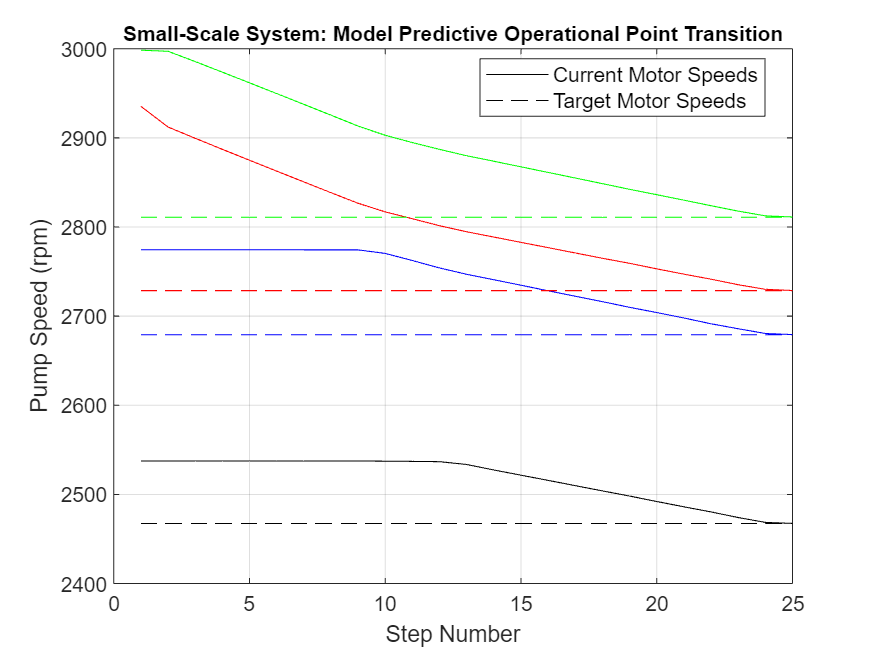

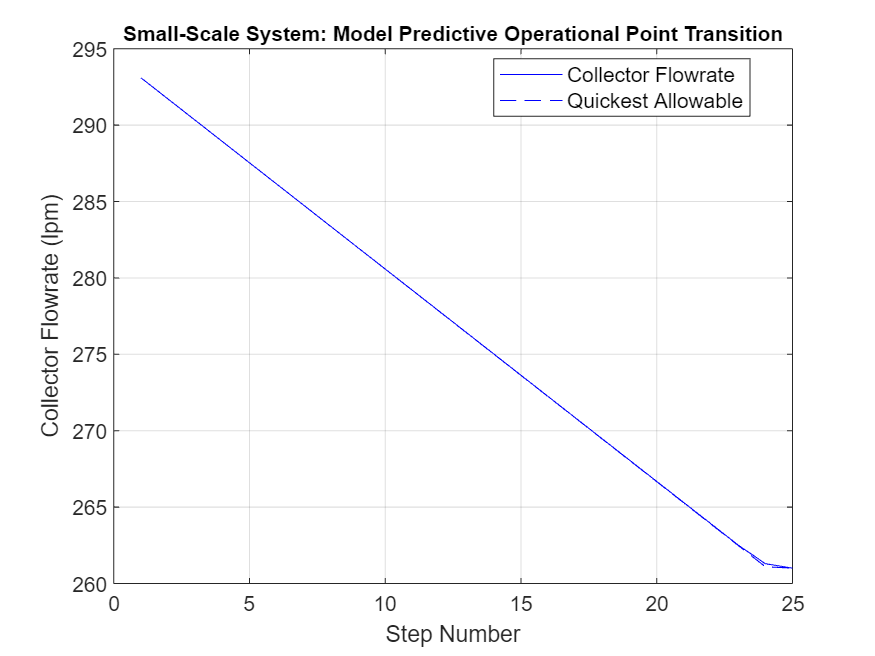


fixedVariables.collector_pressure = fv(1);
fixedVariables.source_pressure_1 = fv(2);
fixedVariables.source_pressure_2 = fv(3);
fixedVariables.source_pressure_3 = fv(4);
fixedVariables.source_pressure_4 = fv(5);

addpath("./Examples/")
example1(fixedVariables,x_s,x_e,limit);

pause(1)



















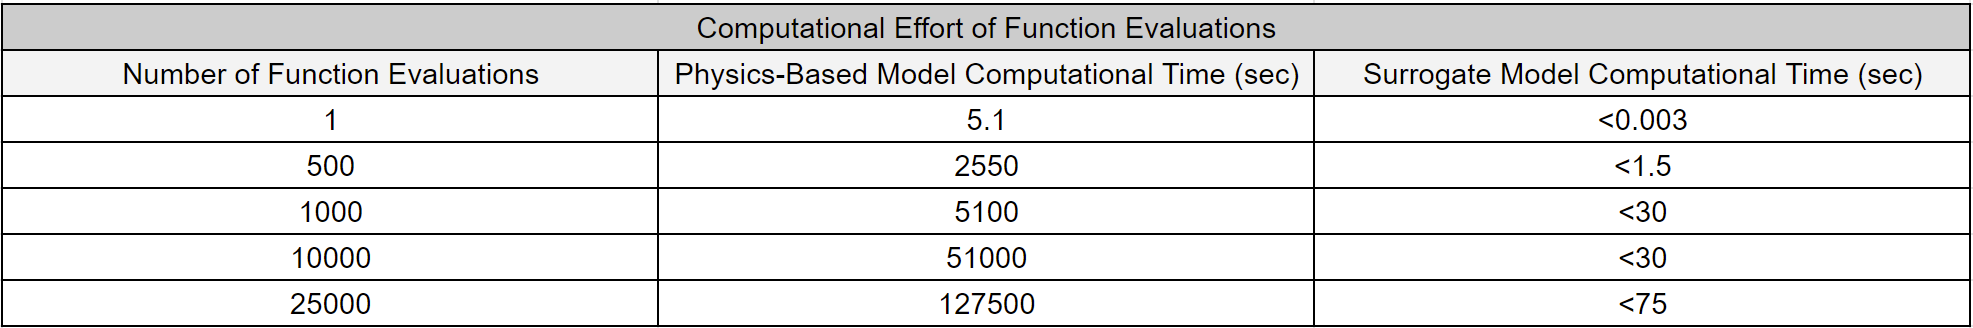

### Example 2: Small-Scale with Collector Flowrate Change and Motor Speed Limits

This example limits the rate of change in the motor speeds. In practice, rapidly changing a pump's speed may not be desirable (or even possible). 

To begin, click the button to initiate the optimization process. The initial and target operating points and the specified limits are randomly selected. The optimization process generates a sequence of motor speeds and the expected flow rate at each intermediate transition step.

 
fv = rand(5,1).*[0.5;1;1;1;1] + [1;0.5;0.5;0.5;0.5];
x_s = rand(4,1).*550 + 2450;
x_e = rand(4,1).*550 + 2450;
collecFlowRateLimit = rand(1,1) + 0.5;
motorSpeedLimit = rand(1,1)*15 + 5;

disp('Fixed Variables:')

Fixed Variables:


disp(['Pressure Collector (atm): ' num2str(fv(1),'%.2f')])

Pressure Collector (atm): 1.14


disp(['Source 1-4 Pressures (atm): ' num2str(fv(2),'%.2f') ', '...
                                    num2str(fv(3),'%.2f') ', '...
                                    num2str(fv(4),'%.2f') ', '...
                                    num2str(fv(5),'%.2f')])

Source 1-4 Pressures (atm): 0.57, 1.11, 1.36, 0.79


disp('Operational Points:')

Operational Points:


disp(['Inital Motor Speeds (rpm): ' num2str(x_s(1),'%.2f') ', '...
                                    num2str(x_s(2),'%.2f') ', '...
                                    num2str(x_s(3),'%.2f') ', '...
                                    num2str(x_s(4),'%.2f')])

Inital Motor Speeds (rpm): 2991.05, 2667.84, 2916.98, 2629.37


disp(['Target Motor Speeds (rpm): ' num2str(x_e(1),'%.2f') ', '...
                                    num2str(x_e(2),'%.2f') ', '...
                                    num2str(x_e(3),'%.2f') ', '...
                                    num2str(x_e(4),'%.2f')])

Target Motor Speeds (rpm): 2982.39, 2787.32, 2956.43, 2651.27


disp('Change Limits:')

Change Limits:


disp(['Collector Flowrate (lpm): ' num2str(collecFlowRateLimit,'%.4f')])

Collector Flowrate (lpm): 0.5169


disp(['Motor Speed (rpm): ' num2str(motorSpeedLimit,'%.4f')])

Motor Speed (rpm): 12.6896


Model Predictive Operational Transition beginning....
Status Update: Step 10 is complete.
Status Update: Step 20 is complete.
Collector flowrate changed by 9.9768 (lpm) in 20 steps.
Flowrate change limited to 0.51687 (lpm) per step.
Change in pumping speeds limited to 12.6896 (rpm) per step per pump.
A total of 400 optimizations were executed.
The surrogate model was evaluated 51663 times.


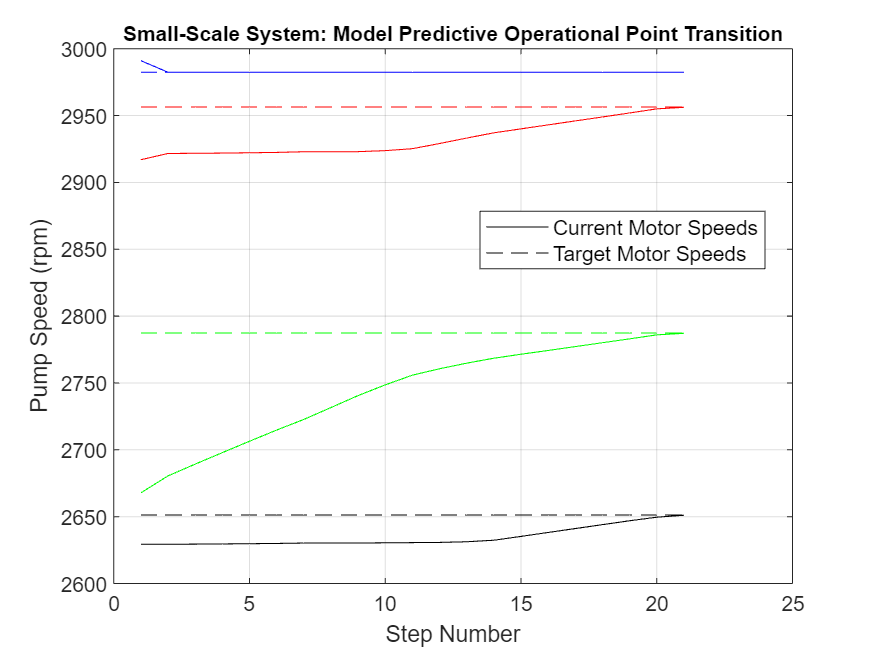

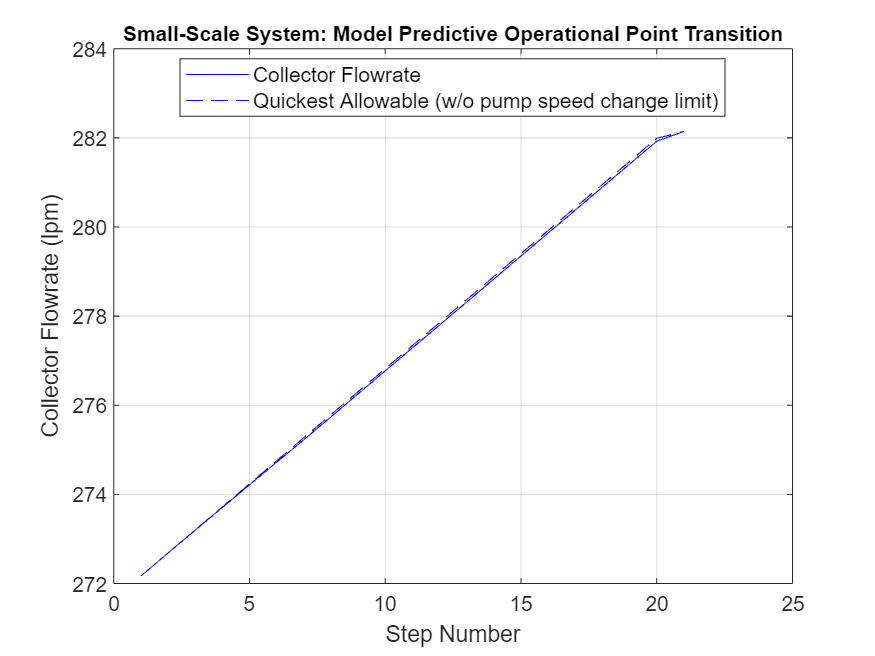


fixedVariables.collector_pressure = fv(1);
fixedVariables.source_pressure_1 = fv(2);
fixedVariables.source_pressure_2 = fv(3);
fixedVariables.source_pressure_3 = fv(4);
fixedVariables.source_pressure_4 = fv(5);

addpath("./Examples/")
pause(1)
example2(fixedVariables,x_s,x_e,collecFlowRateLimit,motorSpeedLimit);

### Example 3: Large-Scale with Subsystem Flowrate Change Limits

The final example uses the large-scale system to demonstrate the framework's effectiveness. We imposed limits on the flow rates of each subsystem and the collector. Recall that there are eight subsystems in the large-scale network, each consisting of multiple lines. Even for the most highly skilled operator, this high-dimensional example would be impossible to solve. 

To begin, click the button to initiate the optimization process. The initial and target operating points and the specified limits are randomly selected.

The first plot illustrates the diminishing "distance" between the current and target operational points. We define "distance" as the sum of differences between target and current speeds across all motors:


$$$$\sum | \omega_{\text{target}} -\omega_{\text{current}}|$$$$


The optimization process also outputs the changes in flow rates at the collector and subsystems normalized by their respective limits. The limit was violated if a normalized flow rate change is more than 1. If the sequence of steps were perfectly efficient, then at least one normalized change in flow rate would always be equal to 1. However, due to the problem's large dimension, the optimization process may not output a perfectly efficient answer. Nevertheless, the optimization process finds a fairly efficient sequence of steps to reach the goal operational point.  

 
x_s = rand(40,1)*550 + 2450;
x_e = rand(40,1)*550 + 2450;
collecFlowRateLimit = rand(1,1)*5.0 + 5.0;
subsystemFlowRateLimit = rand(8,1)*2.5 + 2.5;

disp('Change Limits:')

Change Limits:


disp(['Collector Flowrate (lpm): ' num2str(collecFlowRateLimit,'%.2f')])

Collector Flowrate (lpm): 6.21


disp(['Subsystem Flowrates (lpm): ' num2str(subsystemFlowRateLimit(1),'%.2f') ', '...
                                    num2str(subsystemFlowRateLimit(2),'%.2f') ', '...
                                    num2str(subsystemFlowRateLimit(3),'%.2f') ', '...
                                    num2str(subsystemFlowRateLimit(4),'%.2f') ', '...
                                    num2str(subsystemFlowRateLimit(5),'%.2f') ', '...
                                    num2str(subsystemFlowRateLimit(6),'%.2f') ', '...
                                    num2str(subsystemFlowRateLimit(7),'%.2f') ', '...
                                    num2str(subsystemFlowRateLimit(8),'%.2f')])

Subsystem Flowrates (lpm): 4.57, 4.50, 4.50, 2.74, 4.08, 4.71, 3.24, 3.15


Model Predictive Operational Point Transition beginning....
Status Update: Step 10 is complete.
Status Update: Step 20 is complete.
Collector flowrate changed by 768.8146 (lpm) in 21 steps.
A total of 420 optimizations were executed.
The surrogate model was evaluated 89283 times.


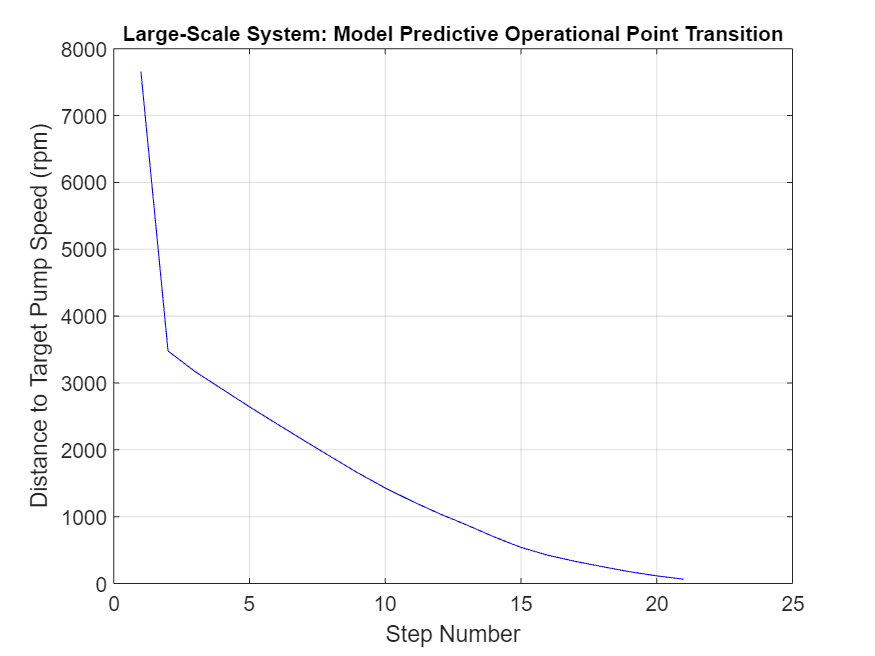

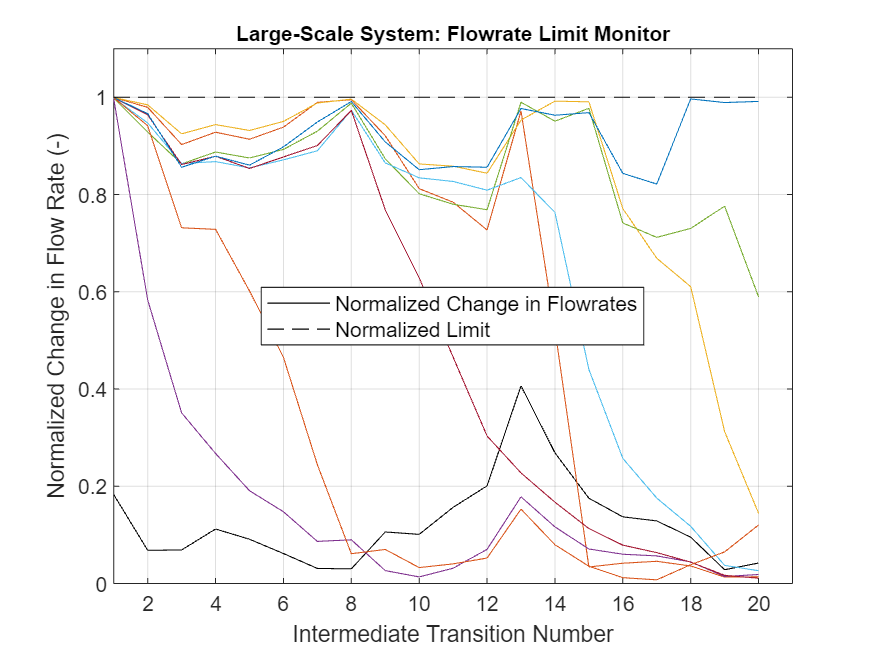



addpath("./Examples/")
pause(1)
example3(x_s,x_e,collecFlowRateLimit,subsystemFlowRateLimit);

## Summary

We demonstrated an exciting use case of the surrogate model-based optimization framework. As shown in example 1, using a physics-based simulator instead of a surrogate model would render this use case infeasible. This article introduces one of the many use cases that only become feasible when a quick and accurate surrogate model is available. 